# Forward Kinematics

close all;
clear all;
clc;

syms alpha0 a0 d1 t1 alpha1 a1 d2 t2 alpha2 a2 d3 t3 alpha3 a3 d4 t4 alpha4 a4 d5 t5 x y z

DH = [0         0       0.4      0; % alpha, a, d, theta - Symbolic
      0         0.325      0       pi/2;
      0         0.225      0       0;
      0         0       -0.29      0];

T_01 = transformationMatrix(DH(1,:));
T_12 = transformationMatrix(DH(2,:));
T_23 = transformationMatrix(DH(3,:));
T_34 = transformationMatrix(DH(4,:));

T_04 = T_01*T_12*T_23*T_34

T_04 =     0.0000   -1.0000         0    0.3250
    1.0000    0.0000         0    0.2250
         0         0    1.0000    0.1100
         0         0         0    1.0000


% simplify(T_04)

## List all points for different trajectories



% Trajectory 1 - From the reference configuration of the arm to the feeder
% T_04 to T_0A 

T_0A = [    0           -1          0           0.325;
            1           0           0           0.225;
            0           0           1           0.100;
            0           0           0           1];

T_0A1 =[    0           -1          0           0.325;
            1           0           0           0.225;
            0           0           1           0.110;
            0           0           0           1];

% Trajectory 2 - From the feeder to the first corner 
% T_0A to T_0A1 to T_0B1 to T_0B
% Trajectory 3 - From the first corner to the feeder

T_0B = [    -1          0           0           0;
            0           -1          0           0.18;
            0           0           1           0.1;
            0           0           0           1];

T_0B1 = [   -1          0           0           0;
            0           -1          0           0.18;
            0           0           1           0.11;
            0           0           0           1];

% Trajectory 4 - From the feeder to the second corner 
% Trajectory 5 - From the second corner to the feeder  

T_0C =  [   0           -1          0           -0.09;
            1           0           0           0.18;
            0           0           1           0.100;
            0           0           0           1];

T_0C1 =  [  0           -1          0           -0.09;
            1           0           0           0.18;
            0           0           1           0.110;
            0           0           0           1];

T_0D = [    1           0           0           -0.09;
            0           1           0           0.27;
            0           0           1           0.1;
            0           0           0           1];

T_0D1 = [   1           0           0           -0.09;
            0           1           0           0.27;
            0           0           1           0.11;
            0           0           0           1];

T_0E =  [   0           1           0           0;
            -1          0           0           0.27;
            0           0           1           0.100;
            0           0           0           1];

T_0E1 =  [  0           1           0           0;
            -1          0           0           0.27;
            0           0           1           0.110;
            0           0           0           1];

% Maximum velocity for each joint

vmax = [(420/180)*pi; (720/180)*pi; (3000/180)*pi; 1.1  ]

vmax =     7.3304
   12.5664
   52.3599
    1.1000


## Define robot

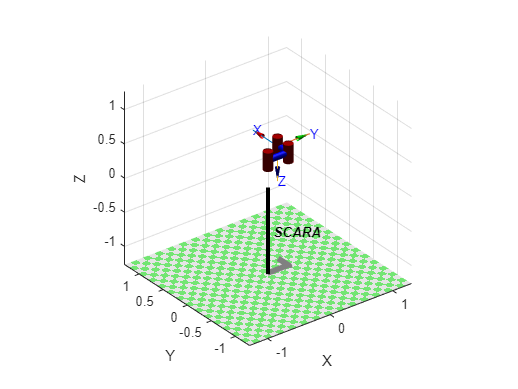


L(1) = Link('revolute','d',0.4,'a',0,'alpha',0,'modified');
L(2) = Link('revolute','d',0,'a',0.325,'alpha',0,'modified');
L(3) = Link('revolute','d',0,'a',0.225,'alpha',0,'modified');
L(4) = Link('prismatic','a',0,'alpha',pi,'modified');
% tool = transl(0, 0, -0.01);
L(4).qlim = [ 0.17  0.32];
% SCARA = SerialLink([L(1),L(2),L(3),L(4)], 'tool', tool);
SCARA = SerialLink([L(1),L(2),L(3),L(4)]);
SCARA.name = 'SCARA';
figure
SCARA.plot([0 pi/2 0 0.01])

## Trajectory 1

thetaI = inverseKinematicsScara(T_04, 0.4, 0.325, 0.225);
thetaA = inverseKinematicsScara(T_0A, 0.4, 0.325, 0.225);

[t, theta] = totalTrajectory(thetaI , thetaI, thetaA, thetaA, vmax)

t =          0         0         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0136    0.0136    0.0136


theta =        NaN       NaN   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000       NaN       NaN
       NaN       NaN    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708       NaN       NaN
       NaN       NaN         0         0         0         0         0         0         0         0       NaN       NaN
       NaN       NaN   -0.2900   -0.2906   -0.2921   -0.2941   -0.2963   -0.2982   -0.2996   -0.3000       NaN       NaN


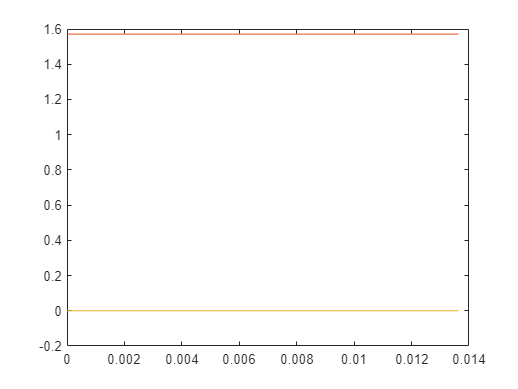


figure
plot(t, theta(1:3, :))

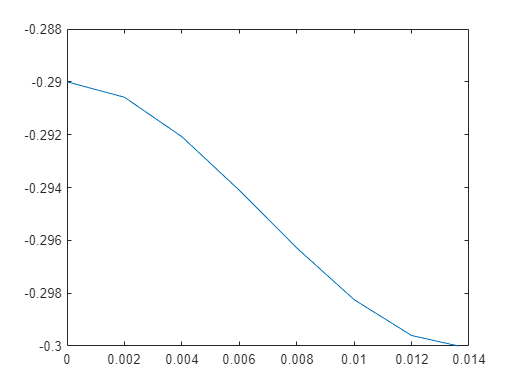

figure
plot(t, theta(4, :))

## Trajectory 2




thetaA1 = inverseKinematicsScara(T_0A1, 0.4, 0.325, 0.225);
thetaB1 = inverseKinematicsScara(T_0B1, 0.4, 0.325, 0.225);
thetaB = inverseKinematicsScara(T_0B, 0.4, 0.325, 0.225);

[t, theta] = totalTrajectory(thetaA , thetaA1, thetaB1, thetaB, vmax)

t =          0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0136    0.0136    0.0156    0.0176    0.0196    0.0216    0.0236    0.0256    0.0276    0.0296    0.0316    0.0336    0.0356    0.0376    0.0396    0.0416    0.0436    0.0456    0.0476    0.0496    0.0516    0.0536    0.0556    0.0576    0.0596    0.0616    0.0636    0.0656    0.0676    0.0696    0.0716    0.0736    0.0756    0.0776    0.0796    0.0816    0.0836    0.0856    0.0876    0.0896    0.0916    0.0936    0.0956


theta =    -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0003    0.0013    0.0030    0.0053    0.0082    0.0117    0.0157    0.0204    0.0256    0.0313    0.0376    0.0444    0.0516    0.0594    0.0676    0.0762    0.0853    0.0948    0.1046    0.1149    0.1255    0.1365    0.1478    0.1594    0.1713    0.1835    0.1960    0.2087    0.2217    0.2349    0.2483    0.2619    0.2757    0.2896    0.3037    0.3179    0.3322    0.3466    0.3611    0.3756    0.3902
    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5712    1.5724    1.5744    1.5771    1.5806    1.5848    1.5897    1.5952    1.6015    1.6083    1.6158    1.6239    1.6326    1.6419    1.6517    1.6621    1.6729    1.6843    1.6961    1.7084    1.7211    1.7342    1.7478    1.7617    1.7759    1.7906    1.8055    1.8207    1.8363    1.8521    1.8681    1.8844    1.9009    1.9175    1.9344    1.9514    1.9685    1.9858    2.0031    2.0205 

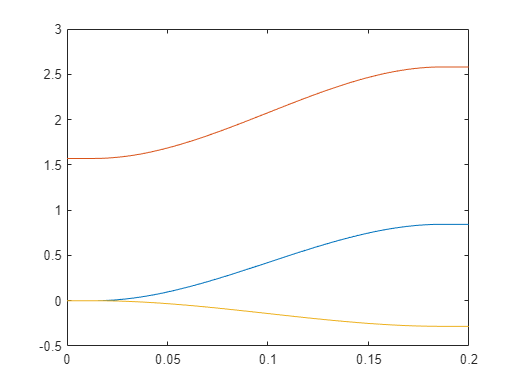


for i=1:4
    theta_d(i, :) = diff(theta(i,1:end))./diff(t);
end

for i=1:4
    theta_dd(i, :) = diff(theta_d(i,1:end))./diff(t(2:end));
end

figure
plot(t, theta(1:3, :))

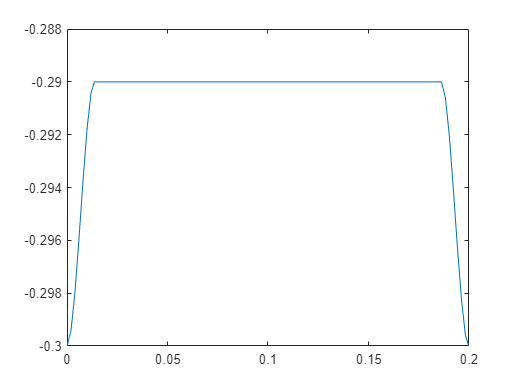

figure
plot(t, theta(4, :))

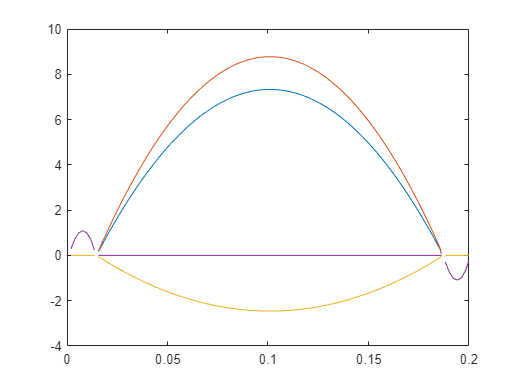


figure
plot(t(2:end),theta_d)

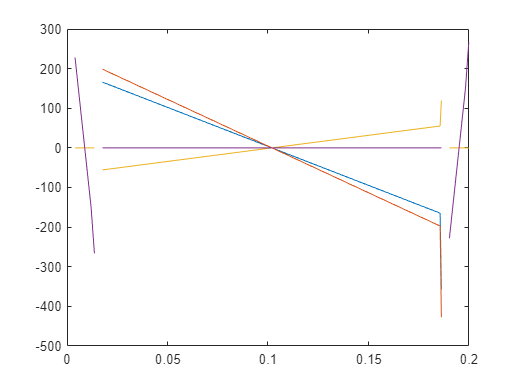


figure
plot(t(3:end), theta_dd)

## Trajectory 3



[t, theta] = totalTrajectory(thetaB , thetaB1, thetaA1, thetaA, vmax)

t =          0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0136    0.0136    0.0156    0.0176    0.0196    0.0216    0.0236    0.0256    0.0276    0.0296    0.0316    0.0336    0.0356    0.0376    0.0396    0.0416    0.0436    0.0456    0.0476    0.0496    0.0516    0.0536    0.0556    0.0576    0.0596    0.0616    0.0636    0.0656    0.0676    0.0696    0.0716    0.0736    0.0756    0.0776    0.0796    0.0816    0.0836    0.0856    0.0876    0.0896    0.0916    0.0936    0.0956


theta =     0.8436    0.8436    0.8436    0.8436    0.8436    0.8436    0.8436    0.8436    0.8436    0.8432    0.8422    0.8406    0.8383    0.8354    0.8319    0.8278    0.8232    0.8179    0.8122    0.8059    0.7992    0.7919    0.7842    0.7760    0.7673    0.7583    0.7488    0.7389    0.7287    0.7180    0.7071    0.6958    0.6841    0.6722    0.6600    0.6475    0.6348    0.6218    0.6086    0.5952    0.5817    0.5679    0.5540    0.5399    0.5257    0.5114    0.4970    0.4825    0.4679    0.4533
    2.5808    2.5808    2.5808    2.5808    2.5808    2.5808    2.5808    2.5808    2.5808    2.5804    2.5792    2.5772    2.5745    2.5710    2.5668    2.5620    2.5564    2.5501    2.5433    2.5358    2.5277    2.5190    2.5097    2.4999    2.4895    2.4787    2.4673    2.4555    2.4432    2.4305    2.4174    2.4039    2.3899    2.3757    2.3611    2.3461    2.3309    2.3153    2.2995    2.2835    2.2672    2.2507    2.2341    2.2172    2.2002    2.1831    2.1658    2.1485    2.1311 

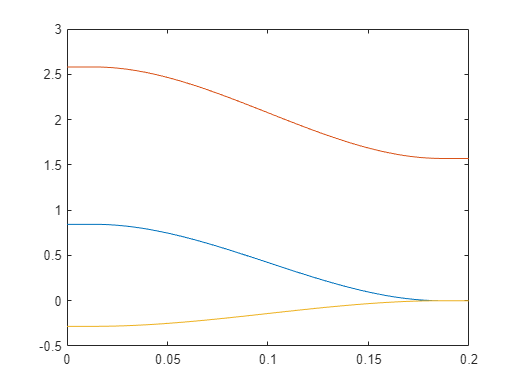


figure
plot(t, theta(1:3, :))

figure
plot(t, theta(4, :))

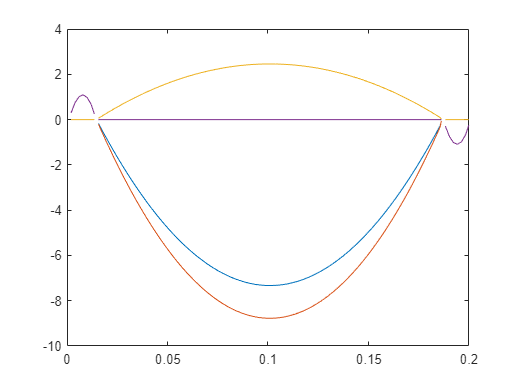


theta_d = [];
theta_dd = [];

for i=1:4
    theta_d(i, :) = diff(theta(i,1:end))./diff(t);
end

for i=1:4
    theta_dd(i, :) = diff(theta_d(i,1:end))./diff(t(2:end));
end

figure
plot(t(2:end),theta_d)

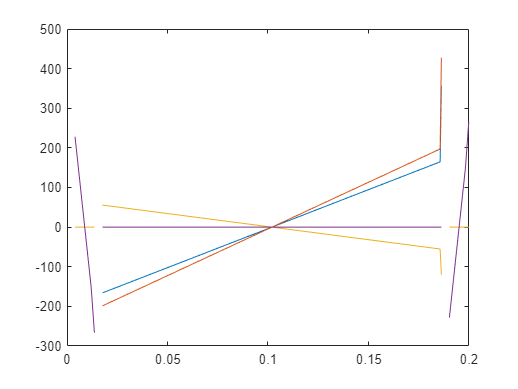


figure
plot(t(3:end), theta_dd)

## Trajectory 4



thetaC1 = inverseKinematicsScara(T_0C1, 0.4, 0.325, 0.225);
thetaC = inverseKinematicsScara(T_0C, 0.4, 0.325, 0.225);


[t, theta] = totalTrajectory(thetaA , thetaA1, thetaC1, thetaC, vmax)

t =          0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0136    0.0136    0.0156    0.0176    0.0196    0.0216    0.0236    0.0256    0.0276    0.0296    0.0316    0.0336    0.0356    0.0376    0.0396    0.0416    0.0436    0.0456    0.0476    0.0496    0.0516    0.0536    0.0556    0.0576    0.0596    0.0616    0.0636    0.0656    0.0676    0.0696    0.0716    0.0736    0.0756    0.0776    0.0796    0.0816    0.0836    0.0856    0.0876    0.0896    0.0916    0.0936    0.0956


theta =    -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0002    0.0009    0.0020    0.0035    0.0054    0.0078    0.0106    0.0137    0.0173    0.0212    0.0255    0.0302    0.0353    0.0407    0.0465    0.0526    0.0590    0.0658    0.0729    0.0803    0.0881    0.0961    0.1044    0.1130    0.1220    0.1311    0.1406    0.1503    0.1603    0.1705    0.1810    0.1917    0.2026    0.2138    0.2251    0.2367    0.2485    0.2604    0.2726    0.2849    0.2975
    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5710    1.5714    1.5722    1.5733    1.5747    1.5764    1.5783    1.5806    1.5831    1.5859    1.5890    1.5923    1.5959    1.5998    1.6039    1.6082    1.6128    1.6177    1.6227    1.6280    1.6335    1.6392    1.6452    1.6513    1.6577    1.6642    1.6709    1.6779    1.6850    1.6922    1.6997    1.7073    1.7151    1.7230    1.7311    1.7394    1.7478    1.7563    1.7650    1.7738 

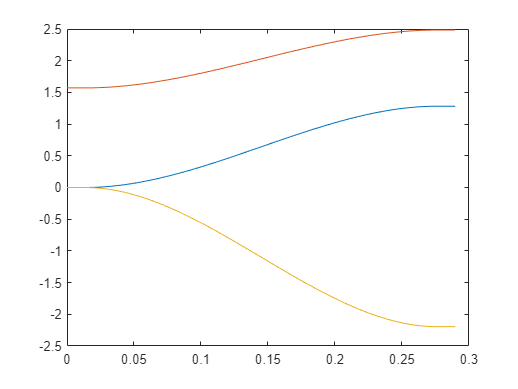


figure
plot(t, theta(1:3, :))

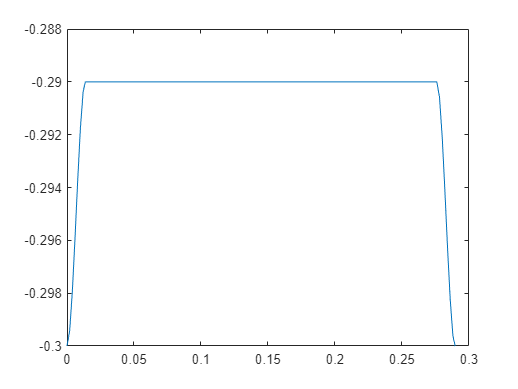

figure
plot(t, theta(4, :))

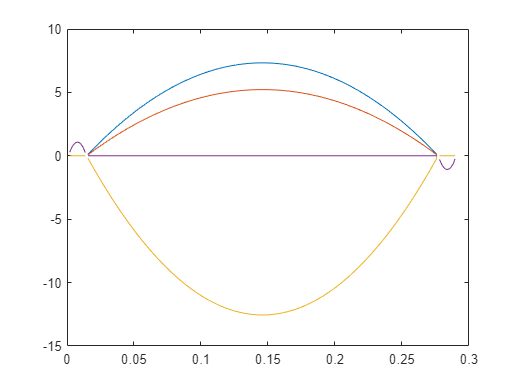


theta_d = [];
theta_dd = [];

for i=1:4
    theta_d(i, :) = diff(theta(i,1:end))./diff(t);
end

for i=1:4
    theta_dd(i, :) = diff(theta_d(i,1:end))./diff(t(2:end));
end

figure
plot(t(2:end),theta_d)

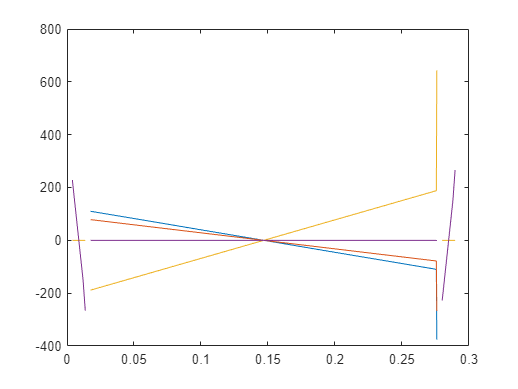


figure
plot(t(3:end), theta_dd)

## Trajectory 5



[t, theta] = totalTrajectory(thetaC , thetaC1, thetaA1, thetaA, vmax)

t =          0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0136    0.0136    0.0156    0.0176    0.0196    0.0216    0.0236    0.0256    0.0276    0.0296    0.0316    0.0336    0.0356    0.0376    0.0396    0.0416    0.0436    0.0456    0.0476    0.0496    0.0516    0.0536    0.0556    0.0576    0.0596    0.0616    0.0636    0.0656    0.0676    0.0696    0.0716    0.0736    0.0756    0.0776    0.0796    0.0816    0.0836    0.0856    0.0876    0.0896    0.0916    0.0936    0.0956


theta =     1.2821    1.2821    1.2821    1.2821    1.2821    1.2821    1.2821    1.2821    1.2821    1.2818    1.2812    1.2801    1.2786    1.2766    1.2743    1.2715    1.2683    1.2648    1.2608    1.2565    1.2518    1.2468    1.2414    1.2356    1.2295    1.2230    1.2163    1.2092    1.2017    1.1940    1.1860    1.1776    1.1690    1.1601    1.1509    1.1415    1.1318    1.1218    1.1116    1.1011    1.0904    1.0795    1.0683    1.0569    1.0454    1.0336    1.0216    1.0095    0.9971    0.9846
    2.4840    2.4840    2.4840    2.4840    2.4840    2.4840    2.4840    2.4840    2.4840    2.4838    2.4833    2.4826    2.4815    2.4801    2.4784    2.4765    2.4742    2.4717    2.4689    2.4658    2.4624    2.4588    2.4550    2.4509    2.4465    2.4419    2.4371    2.4321    2.4268    2.4213    2.4155    2.4096    2.4035    2.3971    2.3906    2.3838    2.3769    2.3698    2.3625    2.3551    2.3475    2.3397    2.3317    2.3236    2.3154    2.3070    2.2985    2.2898    2.2810 

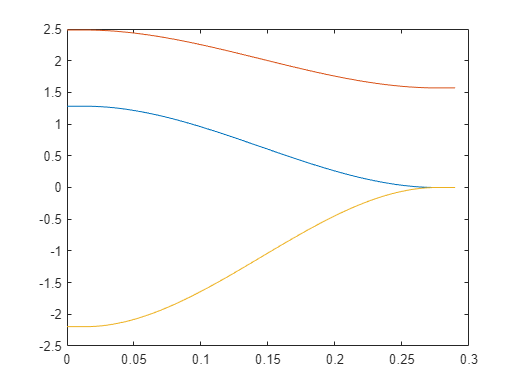


figure
plot(t, theta(1:3, :))

figure
plot(t, theta(4, :))

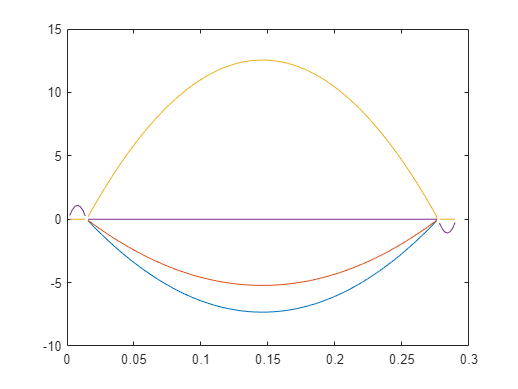


theta_d = [];
theta_dd = [];

for i=1:4
    theta_d(i, :) = diff(theta(i,1:end))./diff(t);
end

for i=1:4
    theta_dd(i, :) = diff(theta_d(i,1:end))./diff(t(2:end));
end

figure
plot(t(2:end),theta_d)

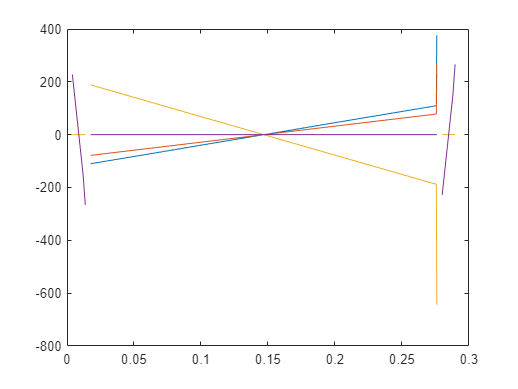


figure
plot(t(3:end), theta_dd)

## Trajectory 6



thetaD1 = inverseKinematicsScara(T_0D1, 0.4, 0.325, 0.225);
thetaD = inverseKinematicsScara(T_0D, 0.4, 0.325, 0.225);


[t, theta] = totalTrajectory(thetaA , thetaA1, thetaD1, thetaD, vmax)

t =          0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0136    0.0136    0.0156    0.0176    0.0196    0.0216    0.0236    0.0256    0.0276    0.0296    0.0316    0.0336    0.0356    0.0376    0.0396    0.0416    0.0436    0.0456    0.0476    0.0496    0.0516    0.0536    0.0556    0.0576    0.0596    0.0616    0.0636    0.0656    0.0676    0.0696    0.0716    0.0736    0.0756    0.0776    0.0796    0.0816    0.0836    0.0856    0.0876    0.0896    0.0916    0.0936    0.0956


theta =    -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0002    0.0010    0.0022    0.0039    0.0061    0.0087    0.0117    0.0153    0.0192    0.0236    0.0283    0.0335    0.0391    0.0451    0.0514    0.0581    0.0652    0.0726    0.0804    0.0885    0.0970    0.1058    0.1148    0.1242    0.1339    0.1439    0.1541    0.1647    0.1754    0.1865    0.1977    0.2092    0.2210    0.2329    0.2451    0.2575    0.2700    0.2828    0.2957    0.3088    0.3221
    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5709    1.5713    1.5718    1.5726    1.5737    1.5749    1.5763    1.5780    1.5798    1.5819    1.5841    1.5866    1.5892    1.5920    1.5950    1.5982    1.6015    1.6050    1.6087    1.6125    1.6165    1.6206    1.6249    1.6293    1.6339    1.6386    1.6434    1.6483    1.6534    1.6586    1.6639    1.6693    1.6749    1.6805    1.6862    1.6921    1.6980    1.7040    1.7101    1.7162 

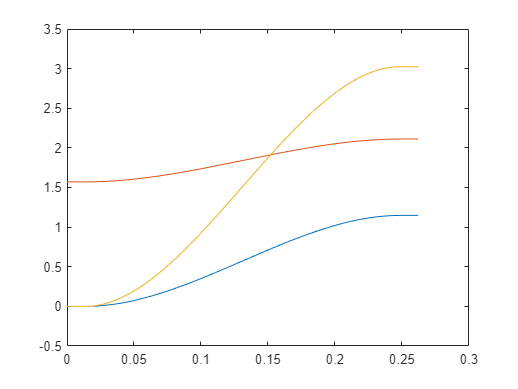


figure
plot(t, theta(1:3, :))

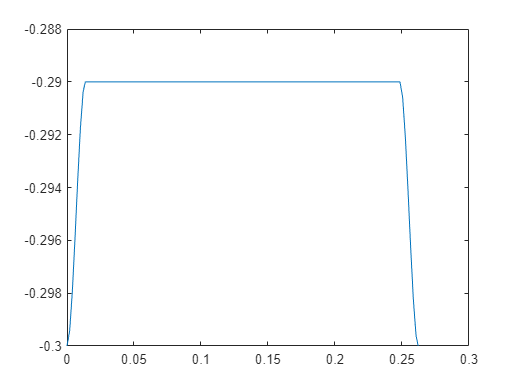

figure
plot(t, theta(4, :))

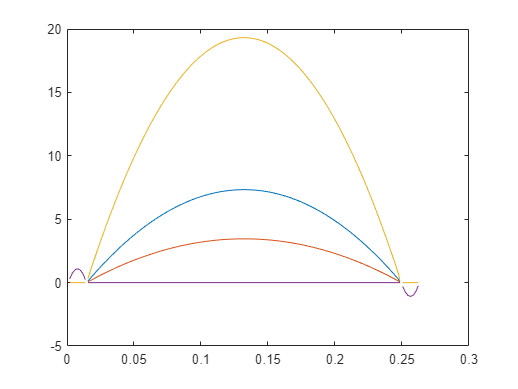


theta_d = [];
theta_dd = [];

for i=1:4
    theta_d(i, :) = diff(theta(i,1:end))./diff(t);
end

for i=1:4
    theta_dd(i, :) = diff(theta_d(i,1:end))./diff(t(2:end));
end

figure
plot(t(2:end),theta_d)

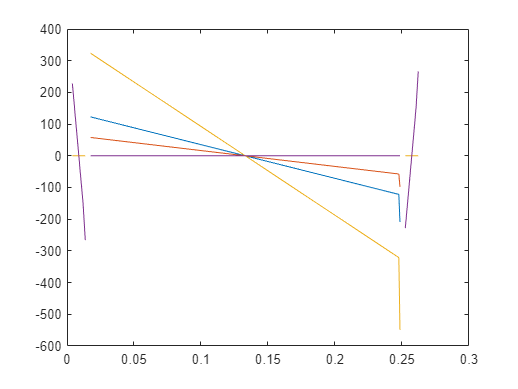


figure
plot(t(3:end), theta_dd)

## Trajectory 7



[t, theta] = totalTrajectory(thetaD , thetaD1, thetaA1, thetaA, vmax)

t =          0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0136    0.0136    0.0156    0.0176    0.0196    0.0216    0.0236    0.0256    0.0276    0.0296    0.0316    0.0336    0.0356    0.0376    0.0396    0.0416    0.0436    0.0456    0.0476    0.0496    0.0516    0.0536    0.0556    0.0576    0.0596    0.0616    0.0636    0.0656    0.0676    0.0696    0.0716    0.0736    0.0756    0.0776    0.0796    0.0816    0.0836    0.0856    0.0876    0.0896    0.0916    0.0936    0.0956


theta =     1.1477    1.1477    1.1477    1.1477    1.1477    1.1477    1.1477    1.1477    1.1477    1.1474    1.1467    1.1454    1.1438    1.1416    1.1390    1.1359    1.1324    1.1285    1.1241    1.1193    1.1141    1.1086    1.1026    1.0963    1.0895    1.0825    1.0750    1.0672    1.0591    1.0507    1.0419    1.0328    1.0234    1.0137    1.0038    0.9935    0.9830    0.9722    0.9612    0.9499    0.9384    0.9267    0.9147    0.9025    0.8902    0.8776    0.8649    0.8519    0.8389    0.8256
    2.1113    2.1113    2.1113    2.1113    2.1113    2.1113    2.1113    2.1113    2.1113    2.1111    2.1108    2.1102    2.1094    2.1084    2.1072    2.1057    2.1041    2.1022    2.1002    2.0979    2.0955    2.0928    2.0900    2.0870    2.0839    2.0806    2.0770    2.0734    2.0696    2.0656    2.0614    2.0572    2.0528    2.0482    2.0435    2.0387    2.0337    2.0286    2.0234    2.0181    2.0127    2.0072    2.0016    1.9958    1.9900    1.9841    1.9781    1.9720    1.9658 

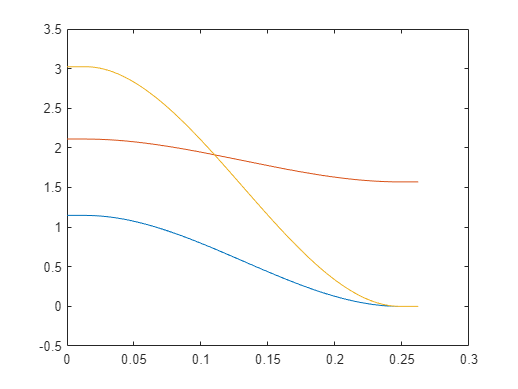


figure
plot(t, theta(1:3, :))

figure
plot(t, theta(4, :))

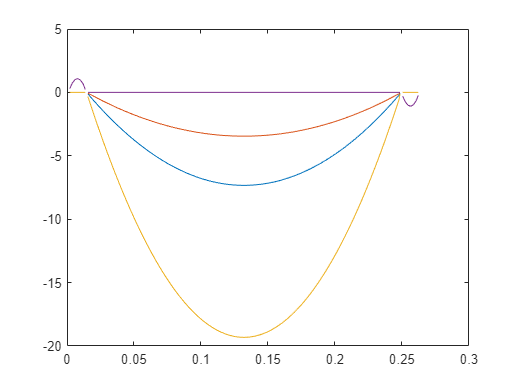


theta_d = [];
theta_dd = [];

for i=1:4
    theta_d(i, :) = diff(theta(i,1:end))./diff(t);
end

for i=1:4
    theta_dd(i, :) = diff(theta_d(i,1:end))./diff(t(2:end));
end

figure
plot(t(2:end),theta_d)

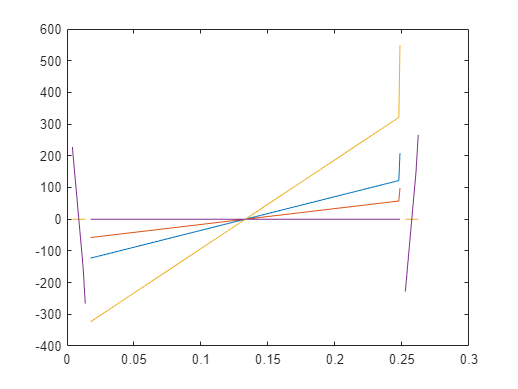


figure
plot(t(3:end), theta_dd)

## Trajectory 8


thetaE1 = inverseKinematicsScara(T_0E1, 0.4, 0.325, 0.225);
thetaE = inverseKinematicsScara(T_0E, 0.4, 0.325, 0.225);


[t, theta] = totalTrajectory(thetaA , thetaA1, thetaE1, thetaE, vmax)

t =          0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0136    0.0136    0.0156    0.0176    0.0196    0.0216    0.0236    0.0256    0.0276    0.0296    0.0316    0.0336    0.0356    0.0376    0.0396    0.0416    0.0436    0.0456    0.0476    0.0496    0.0516    0.0536    0.0556    0.0576    0.0596    0.0616    0.0636    0.0656    0.0676    0.0696    0.0716    0.0736    0.0756    0.0776    0.0796    0.0816    0.0836    0.0856    0.0876    0.0896    0.0916    0.0936    0.0956


theta =    -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0003    0.0014    0.0031    0.0054    0.0084    0.0120    0.0162    0.0210    0.0264    0.0323    0.0387    0.0457    0.0532    0.0611    0.0695    0.0784    0.0877    0.0974    0.1075    0.1180    0.1288    0.1401    0.1516    0.1634    0.1756    0.1880    0.2007    0.2137    0.2269    0.2403    0.2539    0.2676    0.2816    0.2956    0.3099    0.3242    0.3386    0.3531    0.3677    0.3823    0.3970
    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5711    1.5718    1.5731    1.5748    1.5771    1.5797    1.5829    1.5864    1.5904    1.5948    1.5996    1.6047    1.6103    1.6162    1.6224    1.6290    1.6359    1.6431    1.6506    1.6584    1.6665    1.6748    1.6834    1.6922    1.7012    1.7104    1.7199    1.7295    1.7393    1.7492    1.7593    1.7695    1.7799    1.7904    1.8009    1.8116    1.8223    1.8330    1.8439    1.8547 

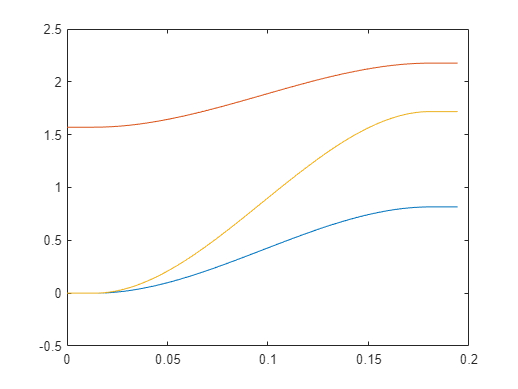


figure
plot(t, theta(1:3, :))

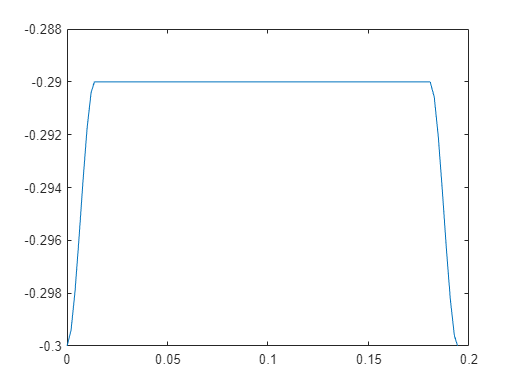

figure
plot(t, theta(4, :))

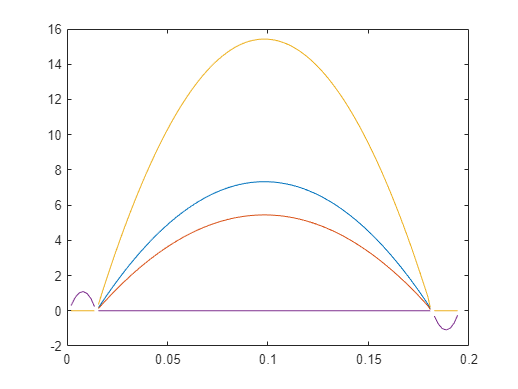


theta_d = [];
theta_dd = [];

for i=1:4
    theta_d(i, :) = diff(theta(i,1:end))./diff(t);
end

for i=1:4
    theta_dd(i, :) = diff(theta_d(i,1:end))./diff(t(2:end));
end

figure
plot(t(2:end),theta_d)

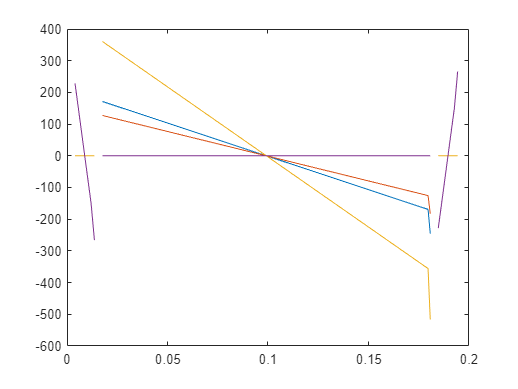


figure
plot(t(3:end), theta_dd)

## Trajectory 9



[t, theta] = totalTrajectory(thetaE , thetaE1, thetaA1, thetaA, vmax)

t =          0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0136    0.0136    0.0156    0.0176    0.0196    0.0216    0.0236    0.0256    0.0276    0.0296    0.0316    0.0336    0.0356    0.0376    0.0396    0.0416    0.0436    0.0456    0.0476    0.0496    0.0516    0.0536    0.0556    0.0576    0.0596    0.0616    0.0636    0.0656    0.0676    0.0696    0.0716    0.0736    0.0756    0.0776    0.0796    0.0816    0.0836    0.0856    0.0876    0.0896    0.0916    0.0936    0.0956


theta =     0.8165    0.8165    0.8165    0.8165    0.8165    0.8165    0.8165    0.8165    0.8165    0.8162    0.8151    0.8134    0.8111    0.8081    0.8045    0.8003    0.7955    0.7901    0.7842    0.7778    0.7708    0.7634    0.7554    0.7470    0.7382    0.7289    0.7191    0.7090    0.6985    0.6877    0.6765    0.6649    0.6531    0.6409    0.6285    0.6158    0.6028    0.5897    0.5763    0.5627    0.5489    0.5350    0.5209    0.5067    0.4923    0.4779    0.4634    0.4488    0.4342    0.4196
    2.1772    2.1772    2.1772    2.1772    2.1772    2.1772    2.1772    2.1772    2.1772    2.1769    2.1762    2.1749    2.1732    2.1709    2.1683    2.1651    2.1616    2.1576    2.1532    2.1484    2.1433    2.1377    2.1318    2.1256    2.1190    2.1121    2.1049    2.0974    2.0896    2.0815    2.0732    2.0646    2.0558    2.0468    2.0376    2.0281    2.0185    2.0087    1.9988    1.9887    1.9784    1.9681    1.9576    1.9471    1.9364    1.9257    1.9149    1.9041    1.8933 

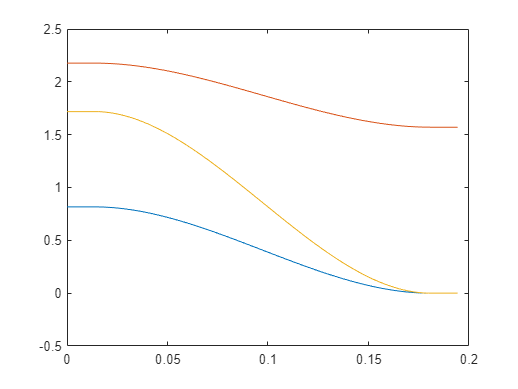


figure
plot(t, theta(1:3, :))

figure
plot(t, theta(4, :))

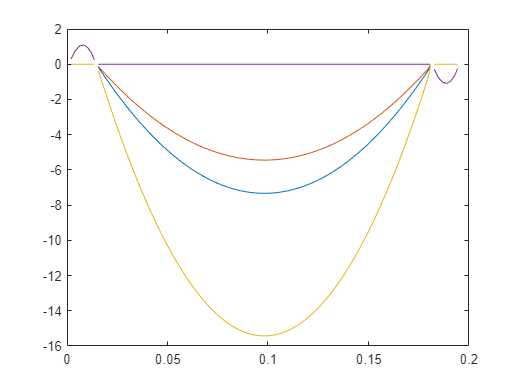


theta_d = [];
theta_dd = [];

for i=1:4
    theta_d(i, :) = diff(theta(i,1:end))./diff(t);
end

for i=1:4
    theta_dd(i, :) = diff(theta_d(i,1:end))./diff(t(2:end));
end

figure
plot(t(2:end),theta_d)

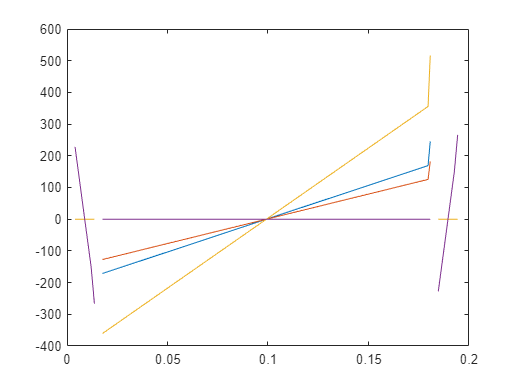


figure
plot(t(3:end), theta_dd)